# Fuzzy Systems - Assignment #3 - Arian Tashakkor - 40023494

## Problem 1

First we will train an ANFIS programmatically. For this problem we have chosen $\#mf = 7$ to keep the number of rules below 50  ($7^2 = 49 < 50$).

warning('off', 'all');
epoch_n = 100;
mf_n = 7;

% ====== collect training data
point_n = 11;
x = linspace(-10, 10, point_n);
y = linspace(-10, 10, point_n);
[xx, yy] = meshgrid(x, y);

zz = (xx.^2 - yy.^2)*sin(xx./2);
trn_data = [xx(:) yy(:) zz(:)];

% ====== training options
ss = 0.1;
ss_dec_rate = 0.9;
ss_inc_rate = 1.1;
mf_type = 'gbellmf';

% ====== generate the initial FIS 
in_fismat = genfis1(trn_data, mf_n, mf_type);

% ====== start training
[trn_out_fismat, trn_error, step_size] = ...
	anfis(trn_data, in_fismat, [epoch_n nan ss ss_dec_rate ss_inc_rate], ...
		[1,1,1,1]);

ANFIS info:
	Number of nodes: 131
	Number of linear parameters: 147
	Number of nonlinear parameters: 42
	Total number of parameters: 189
	Number of training data pairs: 121
	Number of checking data pairs: 0
	Number of fuzzy rules: 49


Start training ANFIS ...

1 	 4.59496
2 	 3.64365
3 	 2.8878
4 	 2.42837
Step size increases to 0.110000 after epoch 5.
5 	 2.11692
6 	 1.83026
7 	 1.55015
8 	 1.32854
Step size increases to 0.121000 after epoch 9.
9 	 1.19757
10 	 1.09258
11 	 1.03145
12 	 0.929942
Step size increases to 0.133100 after epoch 13.
13 	 0.881159
14 	 0.806335
15 	 0.825245
16 	 0.712934
17 	 0.734281
Step size decreases to 0.119790 after epoch 18.
18 	 0.638907
19 	 0.663525
20 	 0.514858
21 	 0.603611
Step size decreases to 0.107811 after epoch 22.
22 	 0.469325
23 	 0.556878
24 	 0.375481
25 	 0.515551
Step size decreases to 0.097030 after epoch 26.
26 	 0.345976
27 	 0.48352
28 	 0.272226
29 	 0.453586
Step size decreases to 0.087327 after epoch 30.
30 	 0.25232
31 	 0.

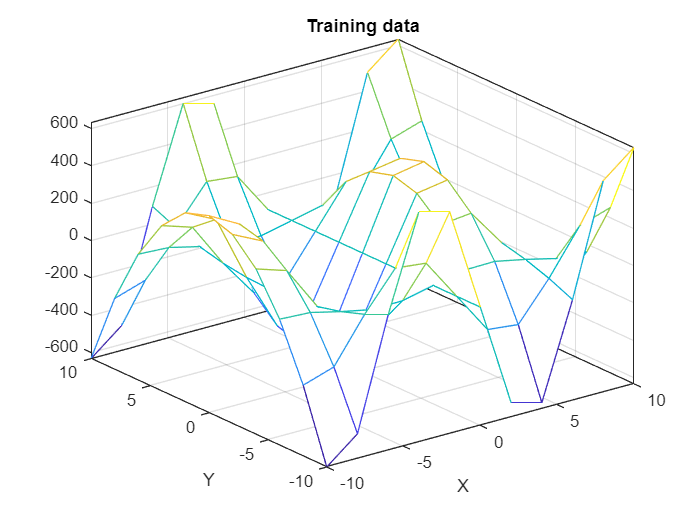

% ====== compute ANFIS output 
z_hat = evalfis([xx(:) yy(:)], trn_out_fismat);

% ====== plot of training data
mesh(xx, yy, zz);
limit = [min(xx(:)) max(xx(:)) min(yy(:)) max(yy(:)) ...
	min(zz(:)) max(zz(:))];
axis(limit); set(gca, 'box', 'on');
xlabel('X'); ylabel('Y'); title('Training data');
hold off

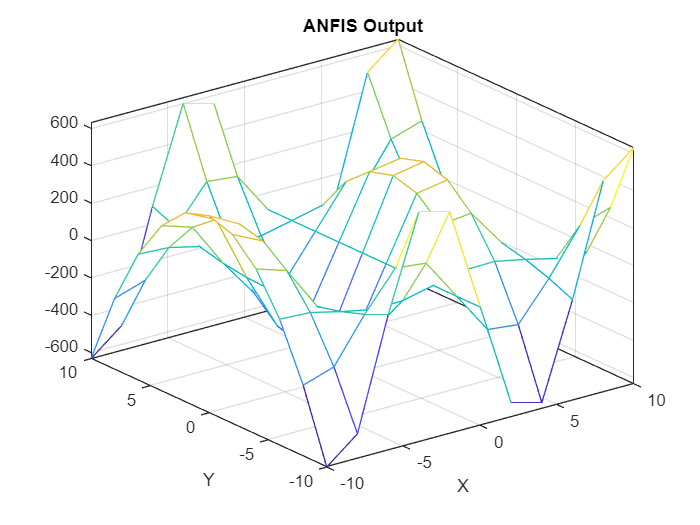


zz_hat = evalfis([xx(:) yy(:)], trn_out_fismat);
mesh(xx, yy, reshape(zz_hat, point_n, point_n));
axis(limit); set(gca, 'box', 'on');
xlabel('X'); ylabel('Y'); title('ANFIS Output');
hold off

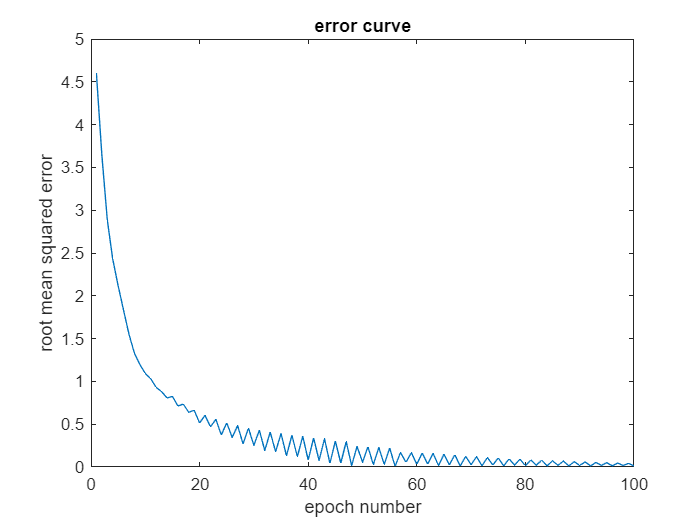


plot(1:epoch_n, trn_error);
xlabel('epoch number'); ylabel('root mean squared error');
title('error curve');
hold off

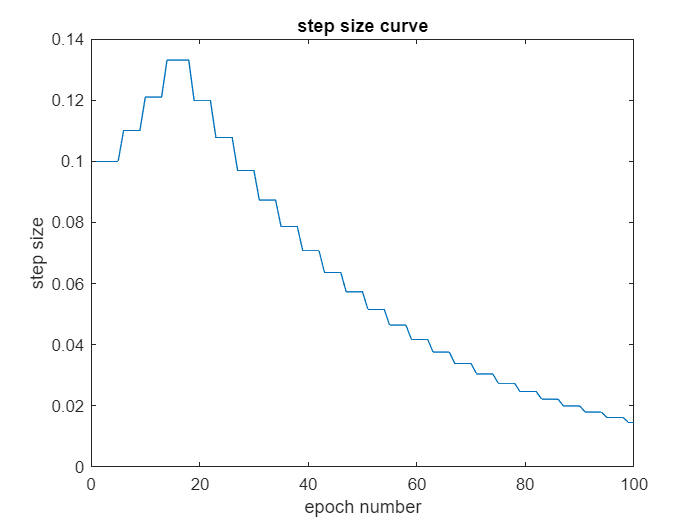


plot(1:epoch_n, step_size);
xlabel('epoch number'); ylabel('step size');
title('step size curve');
hold off

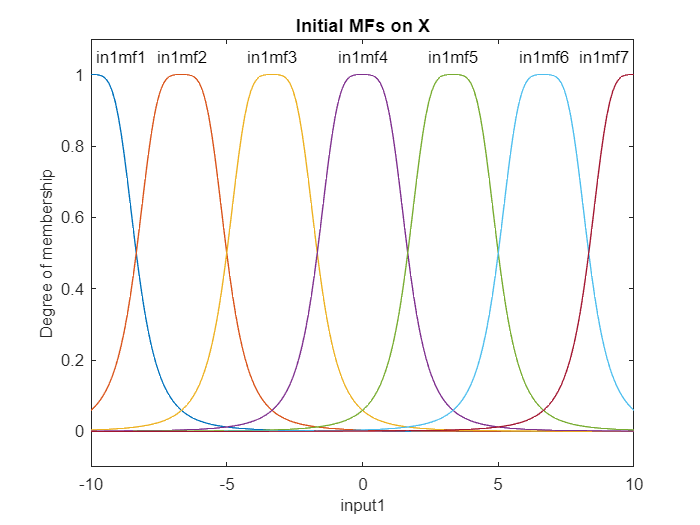

% ====== plot MFs
% plot initial MFs on x and y
plotmf(in_fismat, 'input', 1); title('Initial MFs on X');
hold off

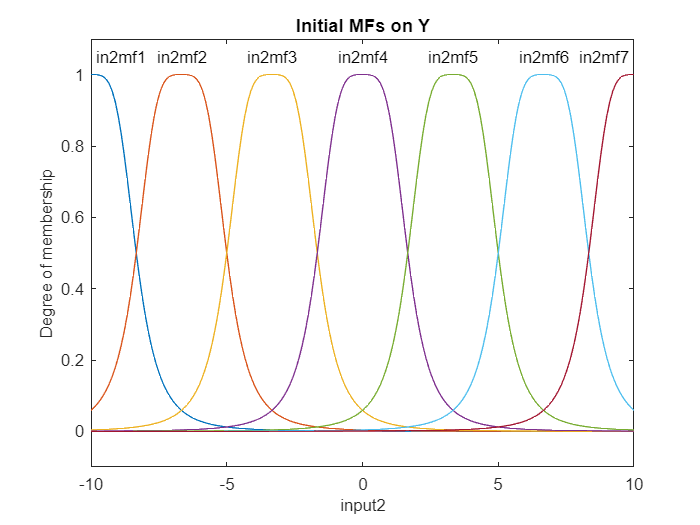

plotmf(in_fismat, 'input', 2); title('Initial MFs on Y');
hold off

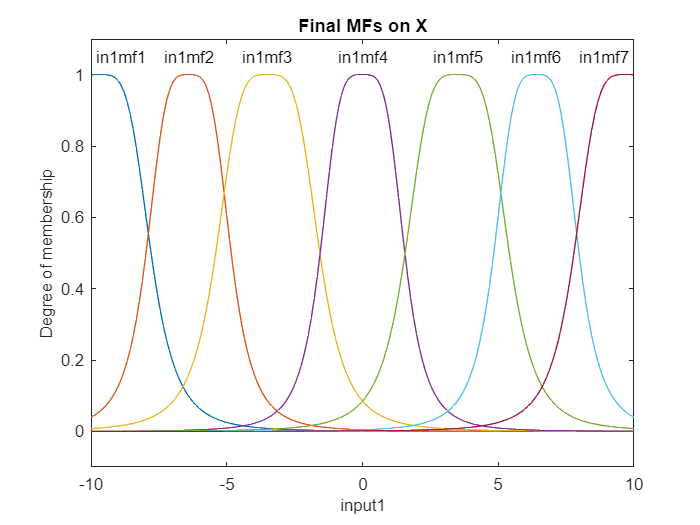

% plot final MFs on X and Y
plotmf(trn_out_fismat, 'input', 1); title('Final MFs on X');
hold off

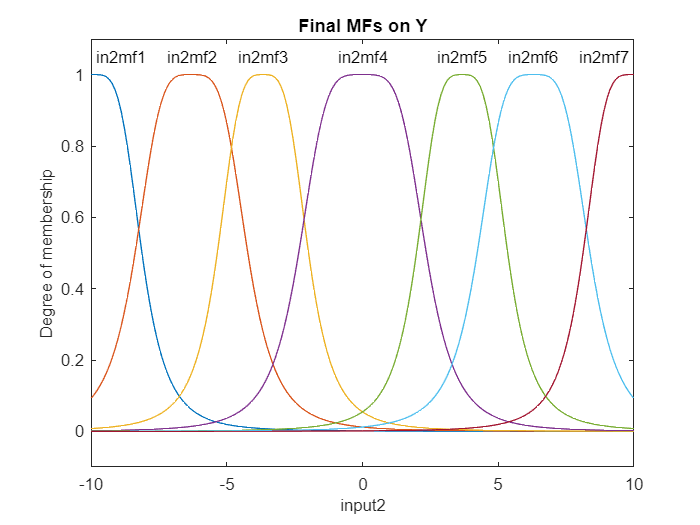

plotmf(trn_out_fismat, 'input', 2); title('Final MFs on Y');
hold off

Next we will do the same thing using the MATLAB Neuro-Fuzzy Designer.

1. First we will load in the training data:

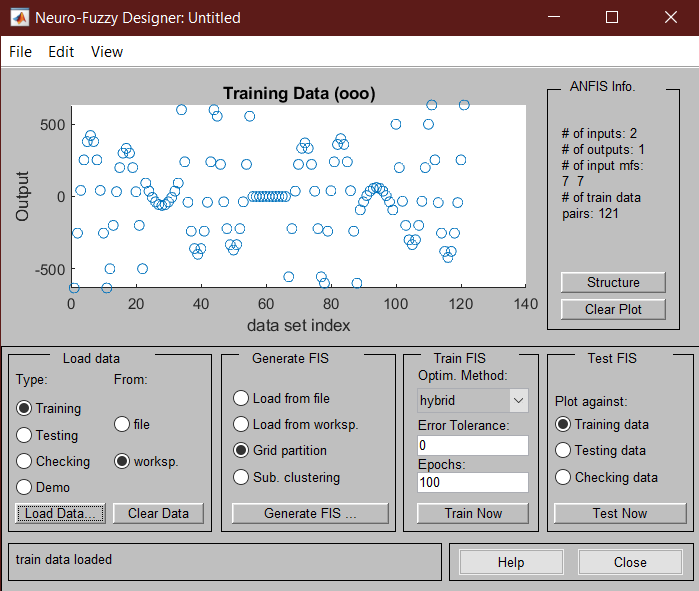

2. Now we will set 7 bell functions per input after pressing "Genearte FIS ...":

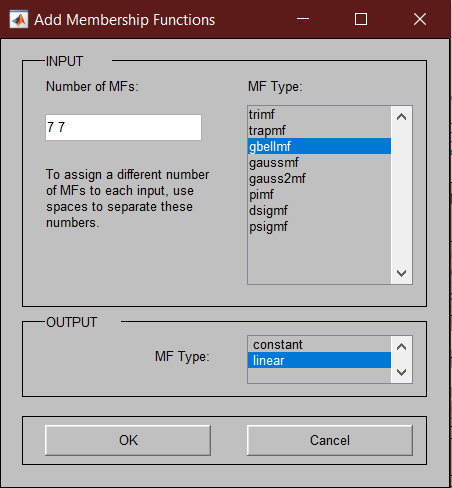

3. Finally we will train for 100 epochs using the hybrid method by setting the number of epochs under the "Epochs" field and pressing "Train Now":

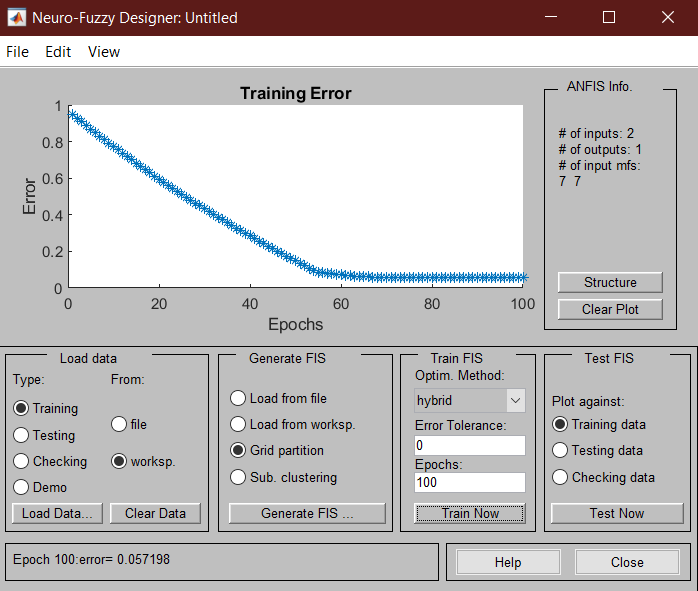

4. We can see the produced surface by the ANFIS using View->Surface:

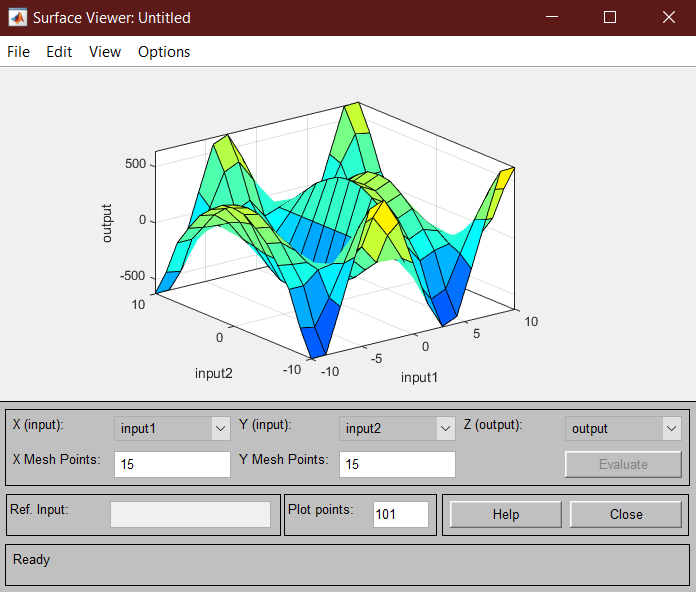

5. Input 1's membership functions after training:

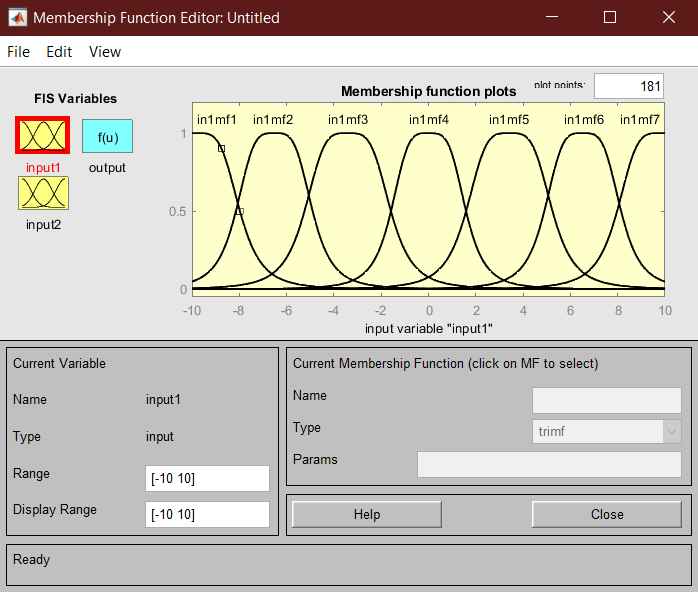

6. Input 2's membership functions after training:

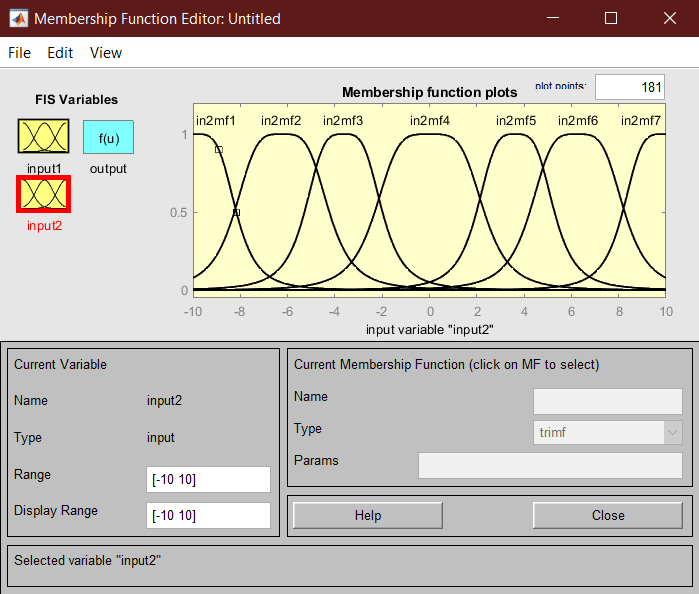

7. And finally network structure: